# Aborsption

Absorption is a widely used separation process in industry. It involves selectively removing a component from a gas stream by passing the gas over the surface of a liquid that preferentially dissolves the desired component.

In an absorption column, we generally use different kinds of packing material. Packing material increases the surface contact between liquid and gas, which ultimately increases the efficiency of the column. Generally, we use countercurrent flow in the absorption tower, where the liquid flows down from top to bottom and the gas flows from bottom to top. This ensures that every time the liquid comes into contact with a new gas stream, the gas is at its highest concentration of the desired component.

The gas stream which has to be treated enters the bottom of the column. The solvent stream enters from the top. The solvent liquid spreads evenly on the packing. Interphase Mass Transfer occurs.

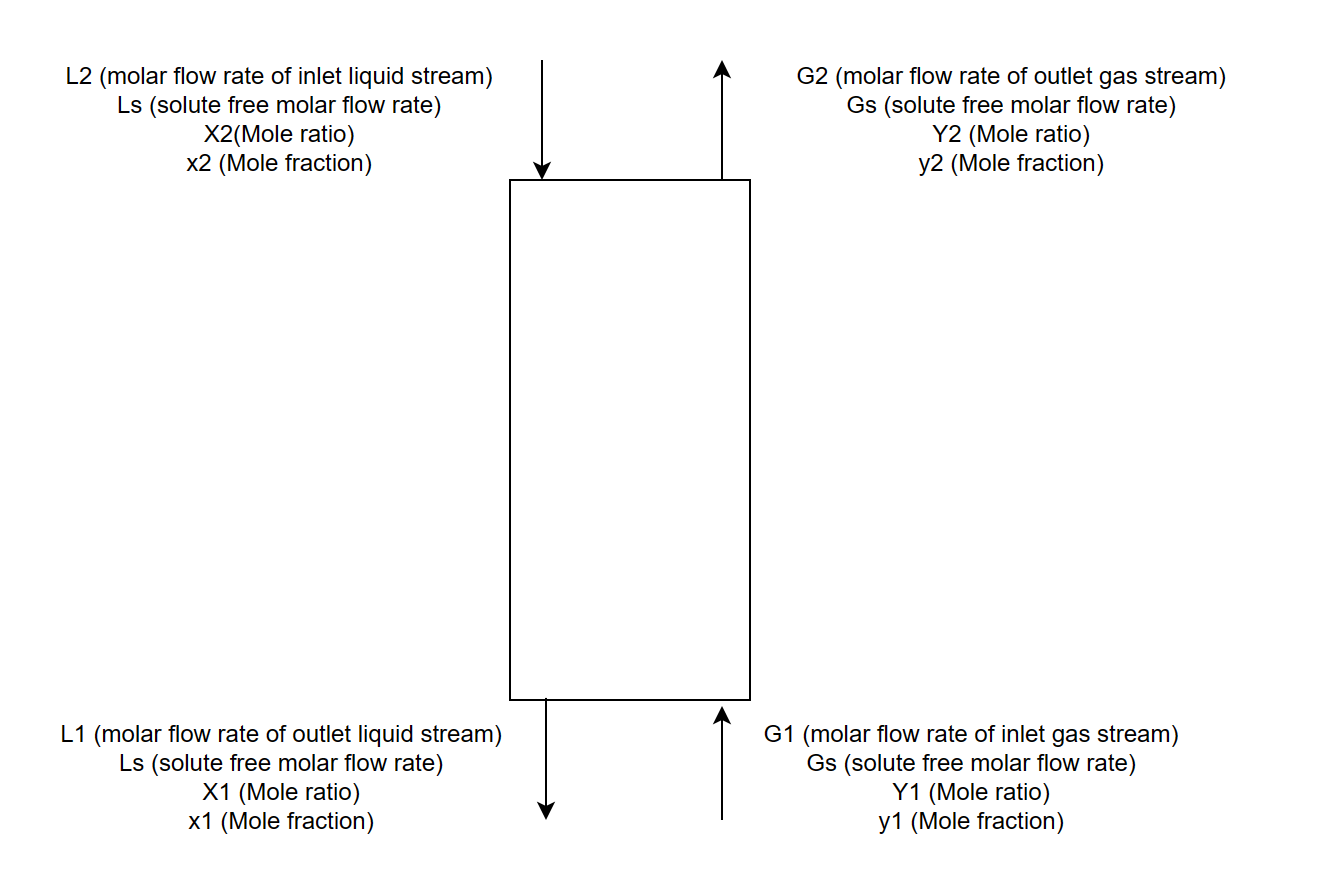

**Calculations steps:**

- From the given data calculate the following values using the following relations:

                
$$L_s =\frac{L_2 }{1+X_2 }$$


                
$$G_s =\frac{G_1 }{1+Y_1 }$$


- Calulate the slope of the operating: $\frac{L_s }{G_s }$

- From the given equilibrium relation express it in the terms of mole ratios using the reations:

            $X=\frac{x}{1-x}$ ;  $Y=\frac{y}{1-y}$

- Plot the equilibrium curve in the X and Y plot and and draw operating line using the given points and with the slope calculated.

- Then using the graph to calulate the number of stages.

% Define input parameters
Y1 = 0.01;  % Feed acetone mole ratio
Y2 = 0.004;  % Desired outlet acetone mole ratio
G1 = 100;  % Feed gas flow rate 
X2 =0.2;  % Initial liquid acetone mole ratio
L2 = 1;  % Liquid flow rate
Ls = L2 / (1 + X2);
Gs = G1 / (1 + Y1);

slopeopl = Ls / Gs;

X1 = X2 + (Y1 - Y2) / slopeopl;
% 
% Data entry method
dataEntryMethod = 'm';  % 'm' or 'Enter values manually'

switch dataEntryMethod
    case 'm'
        m = 0.01;  % Replace with your m value
        X = linspace(X2, X1);
        Y = m .* X ./ (1 + X .* (1 - m));
    case 'manually'
        % Replace with manually entered data
       X = [0, 0.002, 0.004, 0.006, 0.008, 0.01];  % Example values
        Y = [0, 0.005, 0.01, 0.0151, 0.020, 0.025];  % Example values
end

% Define interpolation function
h = griddedInterpolant(X, Y, 'pchip');

% Checking if Y2 is above the equilibrium curve
stopsignal = 0;
Y2_equilibrium = h(X2);

if Y2 < Y2_equilibrium
    errormsg = 'Error: Exit gas concentration is less than Equilibrium Concentration.';
    disp(errormsg);
    stopsignal = 1;
end

% Finding number of stages
n = 0;
maxstagesallowed = 100;
stagepointsx = [];
stagepointsy = [Y1];

if stopsignal == 0
    % Finding whether equilibrium curve and operating line intersect or not
    intersects = @(x) (slopeopl * (x - X2) + Y2 - h(x));
    intrx = fzero(intersects, (X1 + X2) / 2);
    
    if intrx > X2 && intrx < X1
        errormg = 'Liquid rate less than minimum. Please increase L2 and run again.';
        disp(errormg);
    else
        b = X1;
        stagepointsx = [stagepointsx, b];
        
        while n < maxstagesallowed
            yy = h(b);
            stagepointsy = [stagepointsy, yy];
            xx = X2 + (yy - Y2) / slopeopl;
            stagepointsx = [stagepointsx, xx];
            
            if xx > X2
                n = n + 1;
                b = xx;
            else
                yy = h(xx);
                stagepointsy = [stagepointsy, yy];
                break;
            end
        end
        
        disp('Run successful. Check Results.');
    end
end

Run successful. Check Results.


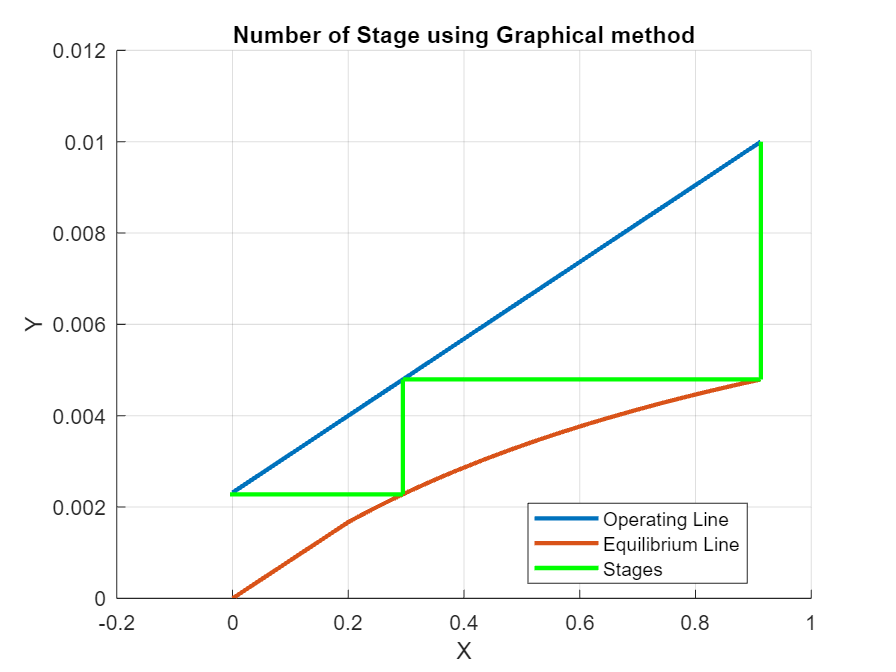


n = n + 1;

% Add (0, 0) to the beginning of X and Y data
X = [0, X];
Y = [0, Y];

% Plotting Equilibrium line and Operating line
opline = @(x) (slopeopl * (x - X2) + Y2);
Ye = opline(X);

figure;
hold on;

plot(X, Ye, 'DisplayName', 'Operating Line','LineWidth', 2);
plot(X, Y, 'DisplayName', 'Equilibrium Line','LineWidth', 2);

lx = length(stagepointsx) - 1;

% Plotting stages
for j = 1:lx
    p1 = [stagepointsx(j) stagepointsx(j)];
    p2 = [stagepointsy(j) stagepointsy(j + 1)];
    plot(p1, p2, 'g','LineWidth', 2);

    p3 = [stagepointsx(j) stagepointsx(j + 1)];
    p4 = [stagepointsy(j + 1) stagepointsy(j + 1)];
    plot(p3, p4, 'g','LineWidth', 2);
end


% Create a single legend entry for stages
title('Number of Stage using Graphical method');
legend('show');
grid('on');
legend('Location', 'best');
legend('Operating Line', 'Equilibrium Line', 'Stages'); % Add 'Stages' to the legend
% Set the title
title('Number of Stage using Graphical method');

% Label the X-axis
xlabel('X');

% Label the Y-axis
ylabel('Y');




disp(['Number of stages: ' num2str(n)]);

Number of stages: 2
